load("carotid.mat");

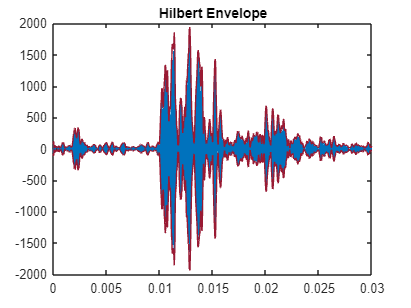

[nRow, nCol] = size(rfdata);
env = abs(hilbert(rfdata));
col=5;

% plotting
figure
plot(axial,rfdata(:,col));
hold on
plot_param = {'Color',[0.6 0.1 0.2],'Linewidth',0.5}; 
plot(axial,env(:,col),plot_param{:})
plot(axial,-env(:,col),plot_param{:})
hold off
title('Hilbert Envelope')

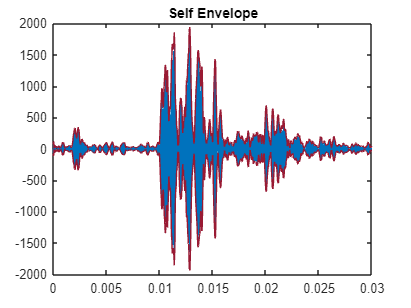

S = (fft(rfdata));
N = length(S);
S(1:N/2,:) = 0;
S(N/2+1:N,:) = 2*S(N/2+1:N,:);
si = ifft((S));

% plotting
figure
plot(axial,rfdata(:,col));
hold on
plot_param = {'Color',[0.6 0.1 0.2],'Linewidth',0.5};
plot(axial,abs(si(:,col)), plot_param{:})
plot(axial,-abs(si(:,col)), plot_param{:})
hold off
title('Self Envelope')

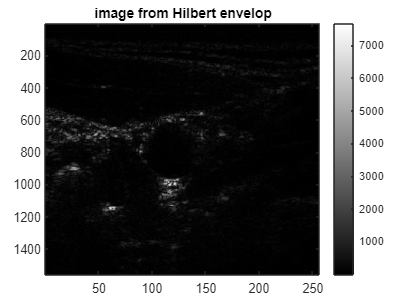

figure
imagesc(env), colormap('Gray'), colorbar
title('image from Hilbert envelop')

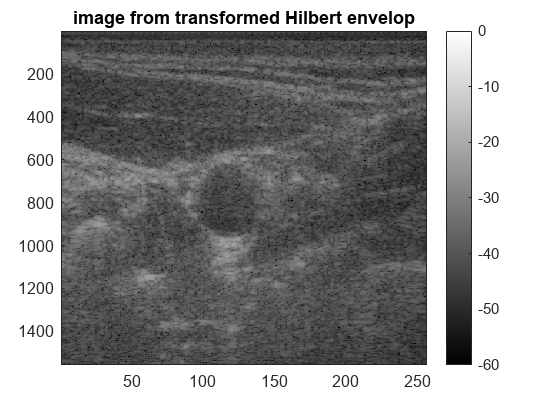


figure
transformedEnv = 10*log10(env/(10^6));
imagesc(transformedEnv,[-60,0]), colormap('Gray'), colorbar
title('image from transformed Hilbert envelop')

'Carotid artery with potential plaques on the right wall is seen'

ans = 'Carotid artery with potential plaques on the right wall is seen'

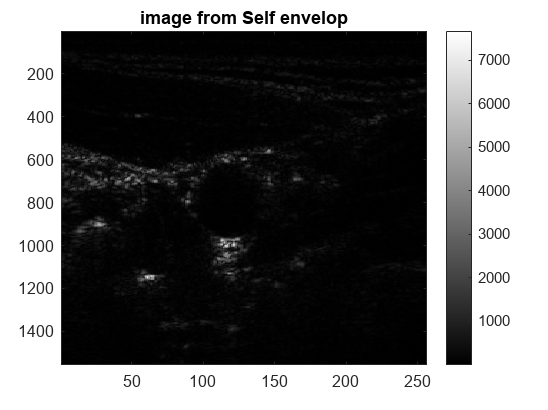



% ---- self envelop
figure
imagesc(abs(si)), colormap('Gray'), colorbar
title('image from Self envelop')

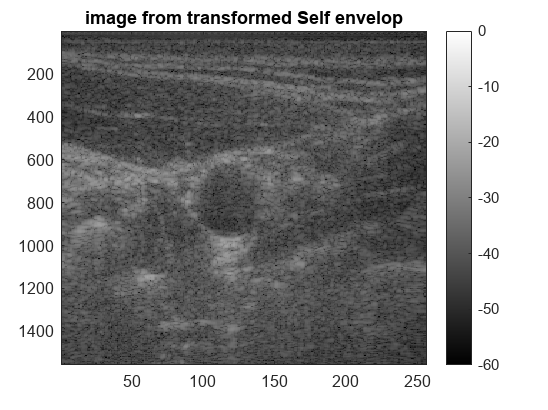


figure
transformedEnv2 = 10*log10(abs(si)/(10^6));
imagesc(transformedEnv2,[-60,0]), colormap('Gray'), colorbar
title('image from transformed Self envelop')

'Carotid artery with potential plaques on the right wall is seen'

ans = 'Carotid artery with potential plaques on the right wall is seen'